Q2)

Same as Q1 but with a perturbed network

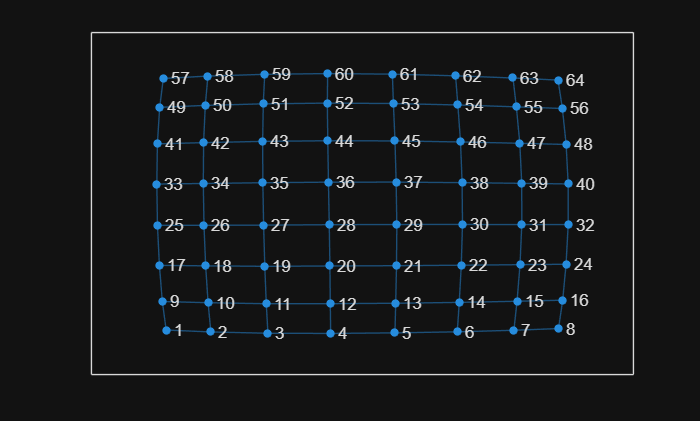

n = 10;     % number of nodes (+2, matlab removes circumfrence nodes) (total=n^2)
L = 0.1;    % length of edges (roads)
L = unifrnd(0, 2*L, (n-2)^2, 1);     % random edge lengths
A = numgrid('S', n);    % grid of nodes
A = -L.*delsq(A);    % convert to sparse adjacency matrix
A = (A + A.')/2;      % convert to symmetric https://uk.mathworks.com/matlabcentral/answers/309569-make-an-existing-matrix-symmetric
% Note the above matrix is actually dense for this example
G = graph(A, 'omitselfloops');     % only use upper portion of adjacency
% h = plot(G);  % dont know why this line plots wrong
figure
plot(G)

% adding euclidean coordinates for nodes
% h.XData = L*floor((0:(n-2)^2-1)/10);
% h.YData = L*rem((0:(n-2)^2-1), 10);



c)

Closing streets/converting to one way and investigating connectivity

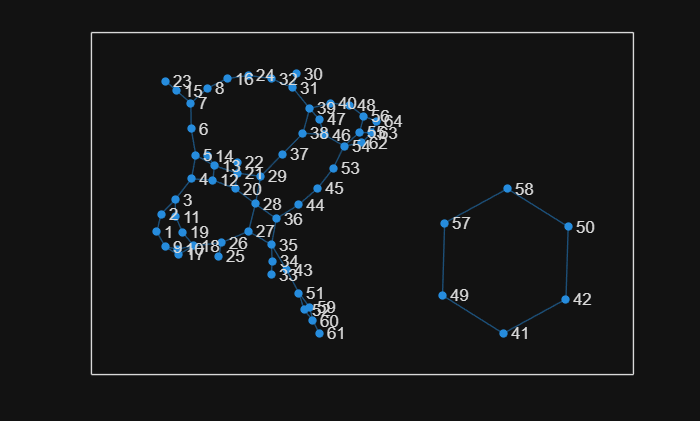


while true
    node_A = randi(G.numnodes);
    node_B = randi(G.numnodes);
    G_temp = G.rmedge(node_A, node_B);

    connected = max(conncomp(G));

    if connected == 1
        G = G_temp;
    else
        break
    end       
end

plot(G)